# Industrial Cutter - Anomaly Detection

#### Autoencoder-based anomaly detection

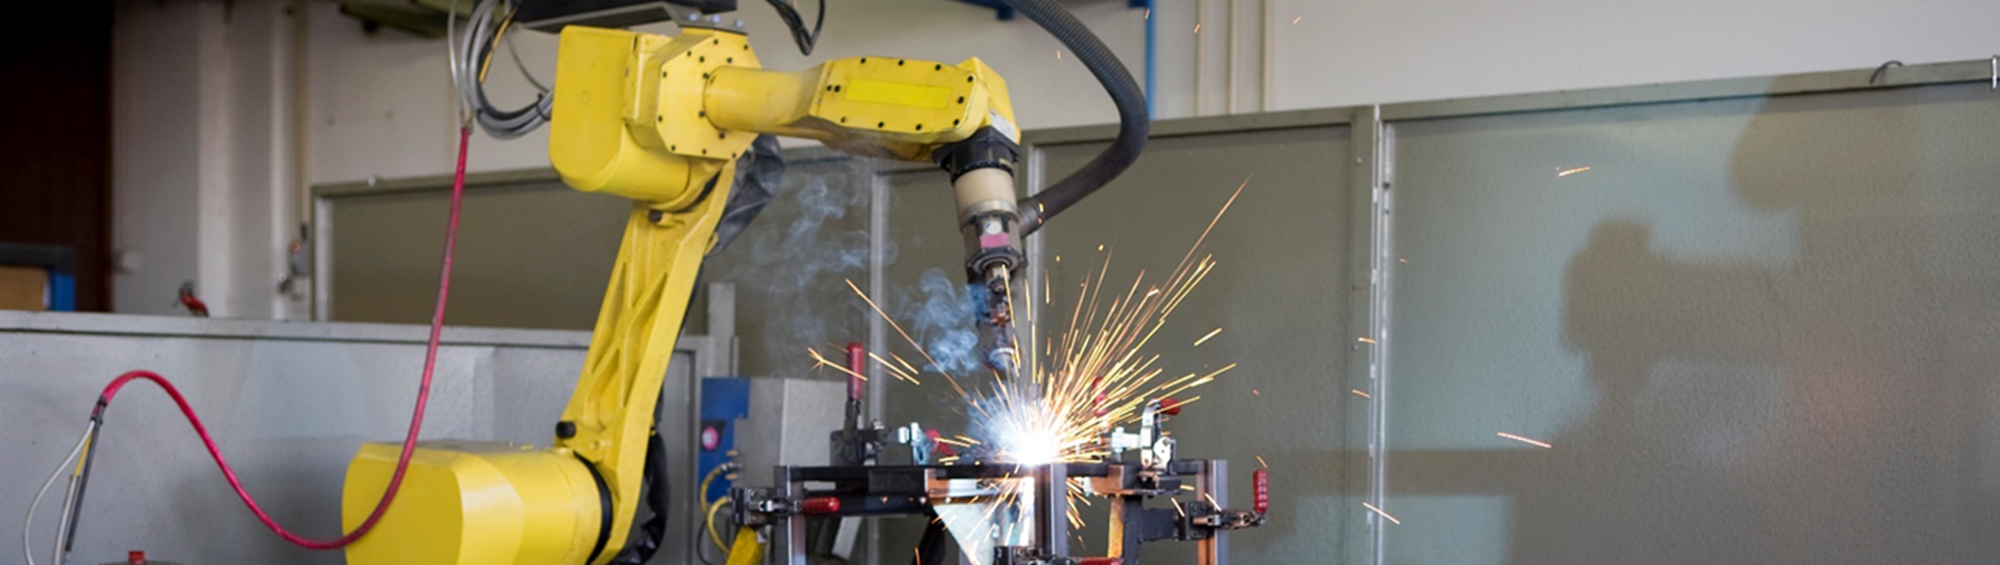

Here is an example where a Deep Learning Autoencoder is trained to detect if a machine metal cutter is working normally or abnormally. It is trained on a set of 12 features, extracted from historical accelerometer data from "normal" operation, which was the time directly after a scheduled maintenance period. Features include mean, standard deviation, kurtosis, crest factor, and were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html).

This trained model is then used to monitor the machine over time. At a certain point the model output differs and drifts from the sensor data output. The more drift, the larger the amount of anomalies are detected which is an indication the machine is acting abnormal.

**Load Historical Features & Labelled State**

The data has 2 labeled states **Before** & **After**. These refer too data collected before and after maintenance.

load("FeatureEntire.mat")

head(feature_All)

ans = 8×13 table
    label     ch1_stats/Col1_CrestFactor    ch1_stats/Col1_Kurtosis    ch1_stats/Col1_RMS    ch1_stats/Col1_Std    ch2_stats/Col1_Mean    ch2_stats/Col1_RMS    ch2_stats/Col1_Skewness    ch2_stats/Col1_Std    ch3_stats/Col1_CrestFactor    ch3_stats/Col1_SINAD    ch3_stats/Col1_SNR    ch3_stats/Col1_THD
    ______    __________________________    _______________________    __________________    __________________    ___________________    __________________    _______________________    __________________    __________________________    ____________________    

**Split into Training & Validation Datasets**

rng(0) % set for reproducibility

idx = cvpartition(feature_All.label, 'holdout', 0.1);
feature_train = feature_All(idx.training, :);
feature_val = feature_All(idx.test, :);

**Model Training**

The model is going to be trained on data **After** maintenance. This is the time when the machine is running "normally".

doTraining = false; % Select if you would like the model to train or use the pretrained model on file

X = extractLabeledData(feature_train, ...
    "Label", "After");

featureDimension = 1;

% Define biLSTM network layers
layers = [ sequenceInputLayer(featureDimension, 'Name', 'in')
    bilstmLayer(16, 'Name', 'bilstm1')
    reluLayer('Name', 'relu1')
    bilstmLayer(32, 'Name', 'bilstm2')
    reluLayer('Name', 'relu2')
    bilstmLayer(16, 'Name', 'bilstm3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(featureDimension, 'Name', 'fc')
    regressionLayer('Name', 'out') ];

% Set Training Options
options = trainingOptions('adam', ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 500,...
    'MaxEpochs',500);

if doTraining
    net = trainNetwork(X, X, layers, options);
else
    load("TrainedModel")
end

**Visualize Model Behavior on Validation Data**

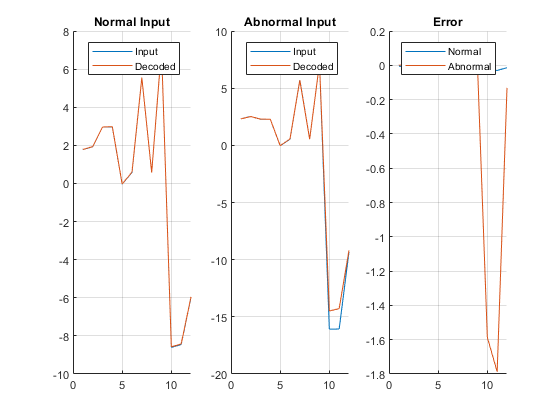

% Extract a sample from Normal(After) and Abnormal(Before)
testNorm = {feature_val(1200, 2:end).Variables}; % 1200 is a sample from After
testAbNorm = {feature_val(200, 2:end).Variables}; % 200 is a sample from Before

% Predict decoded signal for both
decodedNorm = predict(net,testNorm);
decodedAbNorm = predict(net,testAbNorm);

% Visualize
plotError(testNorm, testAbNorm, decodedNorm, decodedAbNorm)

## **Visualize Model Error on Validation Data**

Extract data **Before** and **After **maintenance

% Extract data Before maintenance
XVal_Before = extractLabeledData(feature_val, ...
    "Label", "Before");

% Predict output before maintenance
yHat_Before = predict(net, XVal_Before);

errorBefore = calculateError(XVal_Before, yHat_Before);

% Extract data after maintenance
XVal_After = extractLabeledData(feature_val, ...
    "Label", "After");

% Predict output after maintenance
yHat_After = predict(net, XVal_After);

errorAfter = calculateError(XVal_After, yHat_After);

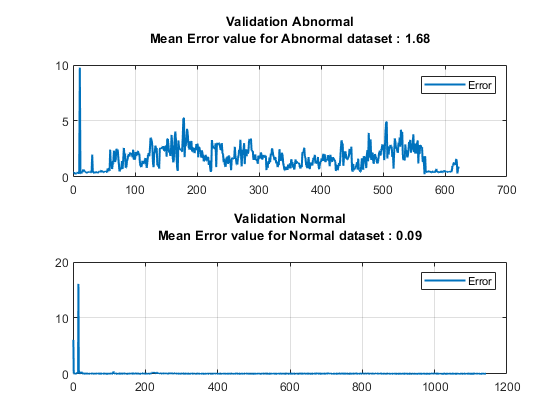

% Plot results
figure("Color", "W")
tiledlayout("flow")

nexttile()
plot(1:length(errorBefore), errorBefore, 'LineWidth',1.5), grid on
title(["Validation Abnormal", ...
    sprintf("Mean Error value for Abnormal dataset : %.2f\n", mean(errorBefore))])
legend('Error')

nexttile()
plot(1:length(errorAfter), errorAfter, 'LineWidth',1.5), grid on,
title(["Validation Normal", ...
    sprintf("Mean Error value for Normal dataset : %.2f\n", mean(errorAfter))])
legend('Error')

**Accuracy for entire dataset**

XVal_All = extractLabeledData(feature_val, ...
    "Label", "All");

yHat_All = predict(net, XVal_All);

errorAll = calculateError(XVal_All, yHat_All);

Define an anomaly as a point which has reconstruction error 0.5 times larger than the mean across all observations.

This threshold was determined through a tuning process, which can be adjusted using the numeric slider below.

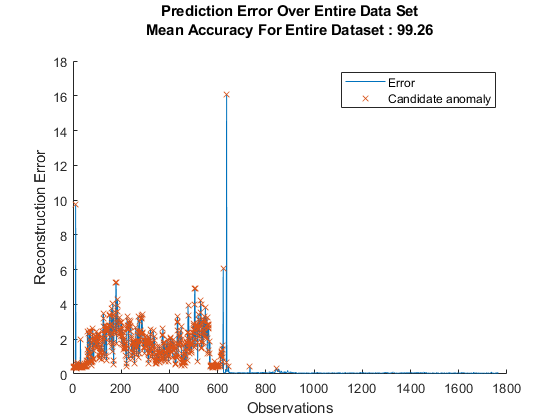

thresh = 0.5;

anomalies = errorAll > thresh*mean(errorAll);
anomalyIdx = find(anomalies);
anomalyErr = errorAll(anomalies);

predAE = categorical(anomalies, [1, 0], {'Before', 'After'})';
acc = numel(find(feature_val.label == transpose(predAE)))/length(predAE)*100;

figure("Color", "W");
hold on
plot(errorAll)
plot(anomalyIdx, anomalyErr, 'x')
hold off
title(["Prediction Error Over Entire Data Set", ...
    sprintf('Mean Accuracy For Entire Dataset : %.2f\n', mean(acc))])
ylabel('Reconstruction Error')
xlabel('Observations')
legend( "Error", "Candidate anomaly" )

# Helper Functions

### Calculate Error

function E = calculateError(X, Y)

E = zeros(length(X),1);
for i = 1:length(X)
    E(i,:) = sqrt(sum((Y{i} - X{i}).^2));
end

end

Copyright 2021 The MathWorks, Inc.